T = readtable('C:\Users\Afshan\Desktop\ai\finalData.xlsx')

T = 1199×6 table
         filename         tempo     spectral_centroid    spectral_bandwidth    rolloff    zero_crossing_rate
    __________________    ______    _________________    __________________    _______    __________________

    {'blues.00081.au'}    103.36         2116.9                1956.6          4196.1           0.12727     
    {'blues.00022.au'}    95.703         1156.1                1497.7          2170.1          0.058613     
    {'blues.00031.au'}       152         1331.1                1973.6          2900.2          0.042967     
    {'blues.00012.au'}    184.57           1361                1567.8          2739.6          0.069124     
    {'blues.00056.au'}     161.5         1811.1                2052.3          3927.8           0.07548     
    {'blues.000

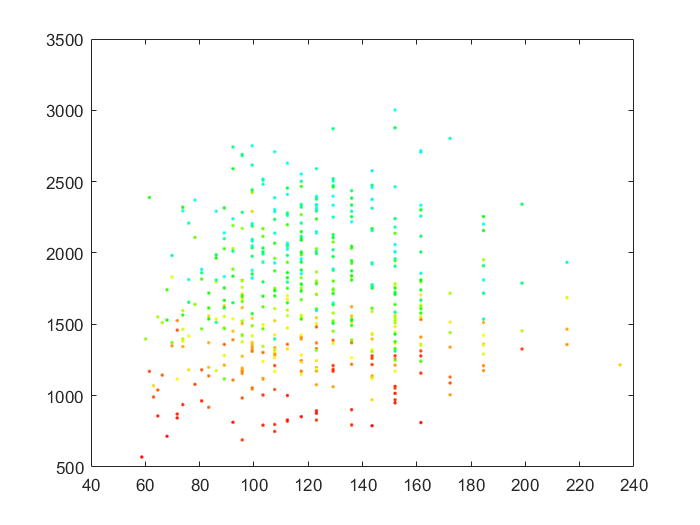

%plotting a scattered plot to visualise the spread of data, since it's 3-D
%plot and we have four features, one feature is not taken into account.
gscatter(T.tempo, T.spectral_centroid, T.spectral_bandwidth)

%Building a machine learning model KNN MODEL - K nearest neighbours.
model = fitcknn(T, "filename")

%predicting values according to the set model, classifying the songs.
PredictSong = predict(model, T)
realvalue = T.filename
%plotting the confusion matrix - this mayrix will show which songs were
%classified as wrong and how many were classified wrong.

C = confusionmat(T.filename, PredictSong)

%finding accuracy by checking the number of correct predictions.
sum = 0
for i = 1:1200
    
    if(PredictSong(i) == realvalue(i))
        sum = sum + 1
    end
end


grid off

accuracy = 0.85

accuracy = 0.8500